## TP FINAL 

#### Garcia Saavedra - Lezama - Nobo

Proyecto en MATLAB para estimar el tamaño de la cavidad del ventrículo izquierdo (VI) y la fracción de eyección sistólica a partir de imágenes de resonancia magnética cardíaca, utilizando diferentes métodos de segmentación.

El proyecto compara cuatro estrategias de segmentación aplicadas a pares de imágenes cardíacas obtenidas durante la diástole y la sístole, e incluye máscaras proporcionadas por expertos que pueden utilizarse como referencia.

Métodos de segmentación utilizados:

- Método 1: morfología matemática

- Método 2: segmentación manual basada en polígonos utilizando `roipoly`

- Método 3: k-means con selección automática del ventrículo izquierdo

- Método 4: detección circular del ventrículo izquierdo utilizando `imfindcircles`

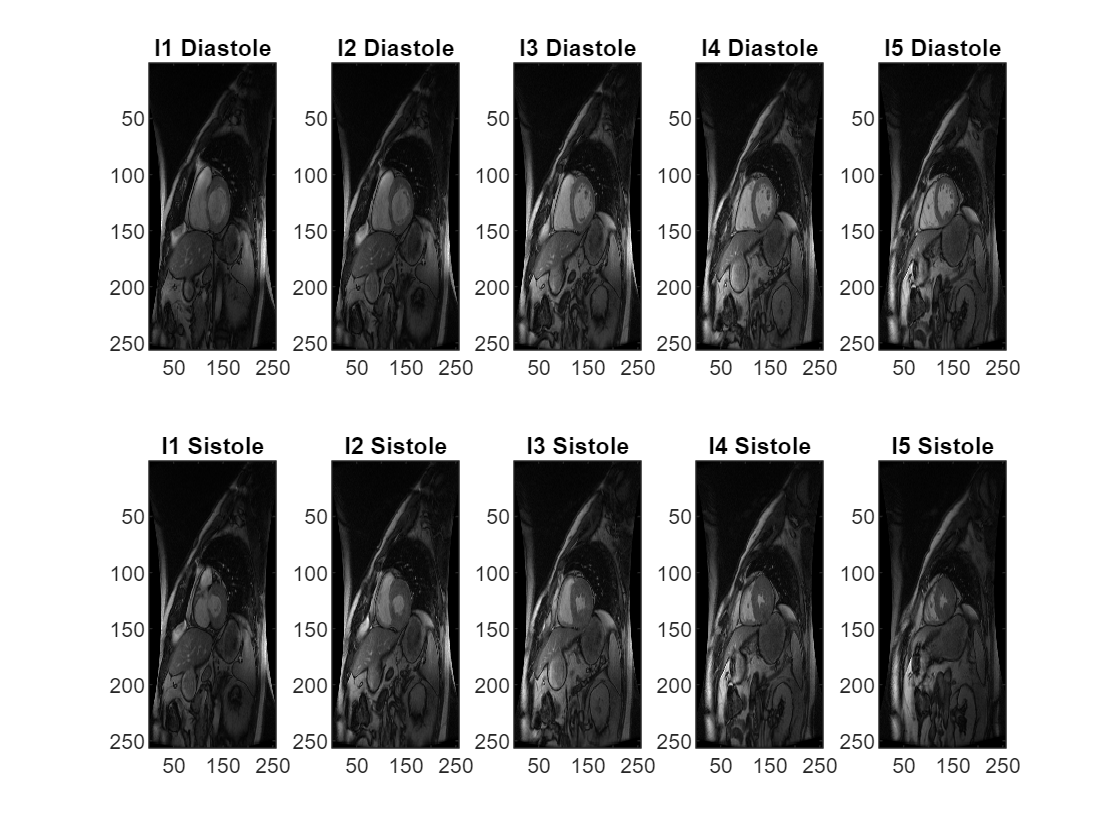

% Almacenando imagenes (D=diastole, S=sistole)
im1_D=dicomread("Images_og\IM-0009-0020.dcm");
im1_S=dicomread("Images_og\IM-0009-0028.dcm");
im2_D=dicomread("Images_og\IM-0009-0040.dcm");
im2_S=dicomread("Images_og\IM-0009-0048.dcm");
im3_D=dicomread("Images_og\IM-0009-0060.dcm");
im3_S=dicomread("Images_og\IM-0009-0068.dcm");
im4_D=dicomread("Images_og\IM-0009-0080.dcm");
im4_S=dicomread("Images_og\IM-0009-0088.dcm");
im5_D=dicomread("Images_og\IM-0009-0100.dcm");
im5_S=dicomread("Images_og\IM-0009-0108.dcm");

% Máscaras proporcionadas por expertos
mask1_D=imread("Expert\IM-0001-0020-icontour-manual.pgm");
mask1_S=imread("Expert\IM-0001-0028-icontour-manual.pgm");
mask2_D=imread("Expert\IM-0001-0040-icontour-manual.pgm");
mask2_S=imread("Expert\IM-0001-0048-icontour-manual.pgm");
mask3_D=imread("Expert\IM-0001-0060-icontour-manual.pgm");
mask3_S=imread("Expert\IM-0001-0068-icontour-manual.pgm");
mask4_D=imread("Expert\IM-0001-0080-icontour-manual.pgm");
mask4_S=imread("Expert\IM-0001-0088-icontour-manual.pgm");
mask5_D=imread("Expert\IM-0001-0100-icontour-manual.pgm");
mask5_S=imread("Expert\IM-0001-0108-icontour-manual.pgm");

% Mostrando imagenes originales
figure;
subplot(2,5,1);
imagesc(im1_D); colormap('gray'); title('I1 Diastole');
subplot(2,5,6);
imagesc(im1_S); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);
imagesc(im2_D); colormap('gray'); title('I2 Diastole');
subplot(2,5,7);
imagesc(im2_S); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);
imagesc(im3_D); colormap('gray'); title('I3 Diastole');
subplot(2,5,8);
imagesc(im3_S); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);
imagesc(im4_D); colormap('gray'); title('I4 Diastole');
subplot(2,5,9);
imagesc(im4_S); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);
imagesc(im5_D); colormap('gray'); title('I5 Diastole');
subplot(2,5,10);
imagesc(im5_S); colormap('gray'); title('I5 Sistole');

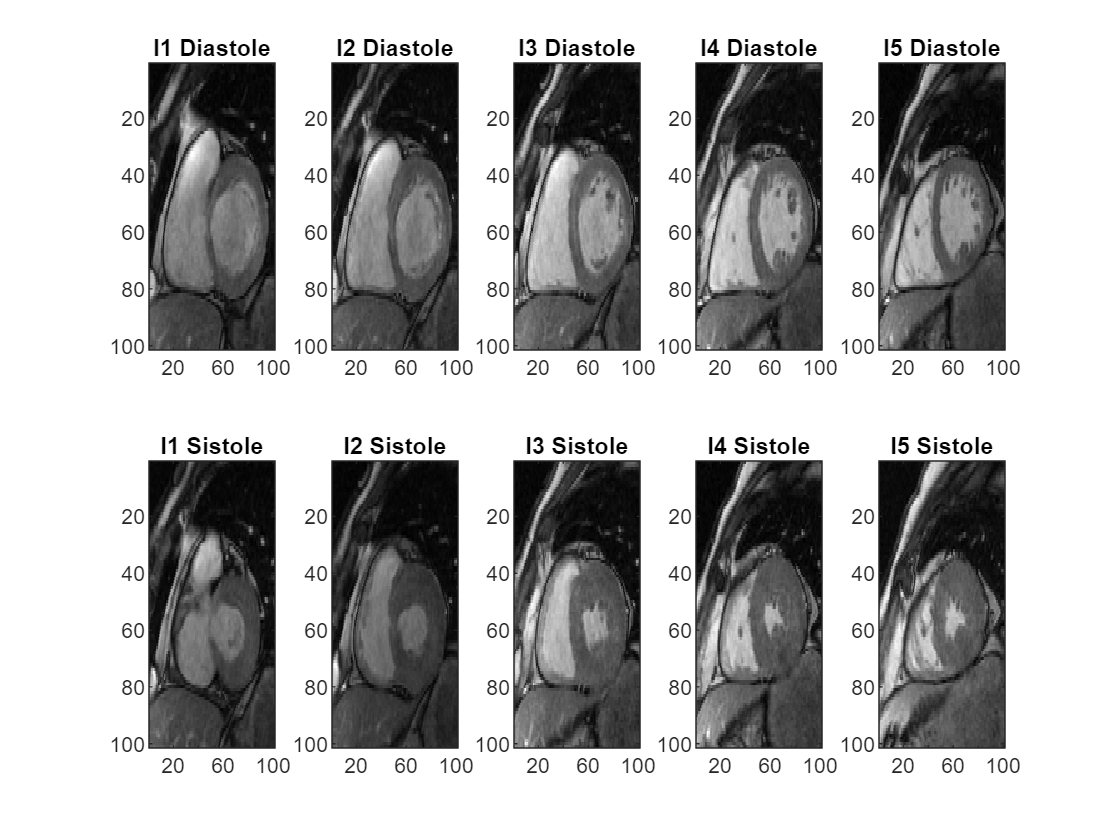

% Recortamos las imagenes en la region de interes

idx1 = 70;  % Inicio de la zona que queremos analizar
idx2 = 170; % Fin de la zona que queremos analizar

im1_D_crop=im1_D(idx1:idx2,idx1:idx2);
im2_D_crop=im2_D(idx1:idx2,idx1:idx2);
im3_D_crop=im3_D(idx1:idx2,idx1:idx2);
im4_D_crop=im4_D(idx1:idx2,idx1:idx2);
im5_D_crop=im5_D(idx1:idx2,idx1:idx2);

im1_S_crop=im1_S(idx1:idx2,idx1:idx2);
im2_S_crop=im2_S(idx1:idx2,idx1:idx2);
im3_S_crop=im3_S(idx1:idx2,idx1:idx2);
im4_S_crop=im4_S(idx1:idx2,idx1:idx2);
im5_S_crop=im5_S(idx1:idx2,idx1:idx2);

% Mostrando imagenes recortadas
figure;
subplot(2,5,1);
imagesc(im1_D_crop); colormap('gray'); title('I1 Diastole');
subplot(2,5,6);
imagesc(im1_S_crop); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);
imagesc(im2_D_crop); colormap('gray'); title('I2 Diastole');
subplot(2,5,7);
imagesc(im2_S_crop); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);
imagesc(im3_D_crop); colormap('gray'); title('I3 Diastole');
subplot(2,5,8);
imagesc(im3_S_crop); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);
imagesc(im4_D_crop); colormap('gray'); title('I4 Diastole');
subplot(2,5,9);
imagesc(im4_S_crop); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);
imagesc(im5_D_crop); colormap('gray'); title('I5 Diastole');
subplot(2,5,10);
imagesc(im5_S_crop); colormap('gray'); title('I5 Sistole');

% Aplicamos una LUT sigmoidea para mejorar el contraste

LUT elegida: $s\left(I\right)=\frac{1}{1+e^{-k\left(I-x_0 \right)} }$

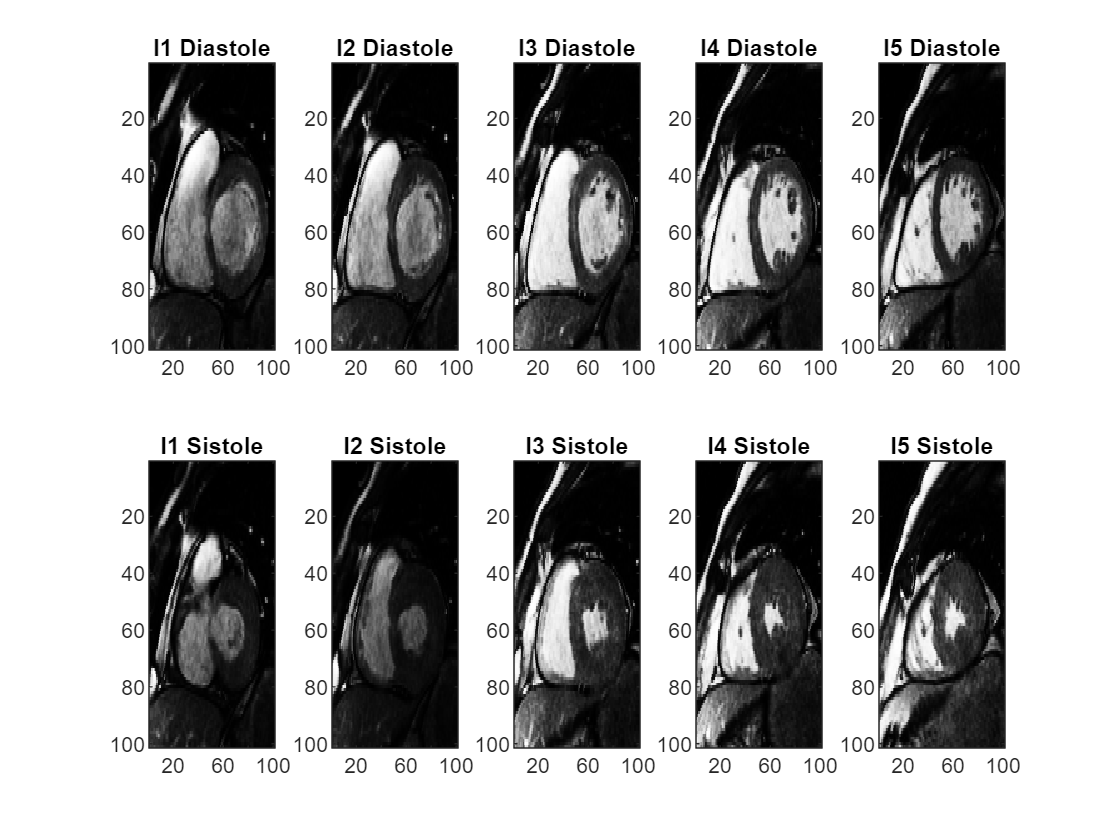

k  = 10;  % Pendiente de la curva S
x0 = 0.5; % Punto medio de la curva S

% Aumenta el contraste alrededor del punto medio
s_curve=@(I) 1./(1 + exp(-k * (I - x0)));

% La aplicamos en las todas las imagenes
im1_S_lut=s_curve(mat2gray(im1_S_crop));
im2_S_lut=s_curve(mat2gray(im2_S_crop));
im3_S_lut=s_curve(mat2gray(im3_S_crop));
im4_S_lut=s_curve(mat2gray(im4_S_crop));
im5_S_lut=s_curve(mat2gray(im5_S_crop));

im1_D_lut=s_curve(mat2gray(im1_D_crop));
im2_D_lut=s_curve(mat2gray(im2_D_crop));
im3_D_lut=s_curve(mat2gray(im3_D_crop));
im4_D_lut=s_curve(mat2gray(im4_D_crop));
im5_D_lut=s_curve(mat2gray(im5_D_crop));

% Mostrando imagenes con la LUT aplicada
figure;
subplot(2,5,1);
imagesc(im1_D_lut); colormap('gray'); title('I1 Diastole');
subplot(2,5,6);
imagesc(im1_S_lut); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);
imagesc(im2_D_lut); colormap('gray'); title('I2 Diastole');
subplot(2,5,7);
imagesc(im2_S_lut); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);
imagesc(im3_D_lut); colormap('gray'); title('I3 Diastole');
subplot(2,5,8);
imagesc(im3_S_lut); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);
imagesc(im4_D_lut); colormap('gray'); title('I4 Diastole');
subplot(2,5,9);
imagesc(im4_S_lut); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);
imagesc(im5_D_lut); colormap('gray'); title('I5 Diastole');
subplot(2,5,10);
imagesc(im5_S_lut); colormap('gray'); title('I5 Sistole');

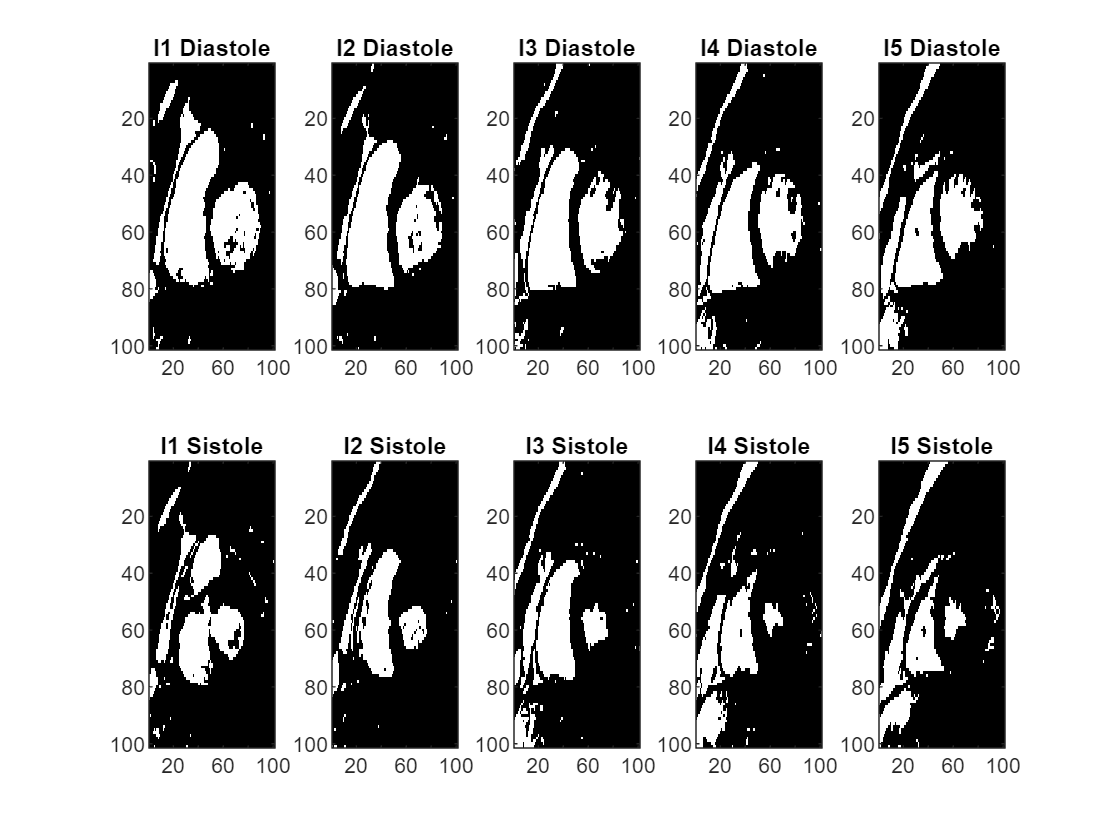

% Binarizacion con umbral elegido automaticamente con Otsu
im1_D_bin=imbinarize(im1_D_lut);
im2_D_bin=imbinarize(im2_D_lut);
im3_D_bin=imbinarize(im3_D_lut);
im4_D_bin=imbinarize(im4_D_lut);
im5_D_bin=imbinarize(im5_D_lut);

im1_S_bin=imbinarize(im1_S_lut);
im2_S_bin=imbinarize(im2_S_lut);
im3_S_bin=imbinarize(im3_S_lut);
im4_S_bin=imbinarize(im4_S_lut);
im5_S_bin=imbinarize(im5_S_lut);

% Mostramos las imagenes binarias
figure;
subplot(2,5,1);
imagesc(im1_D_bin); colormap('gray'); title('I1 Diastole');
subplot(2,5,6);
imagesc(im1_S_bin); colormap('gray'); title('I1 Sistole');

subplot(2,5,2);
imagesc(im2_D_bin); colormap('gray'); title('I2 Diastole');
subplot(2,5,7);
imagesc(im2_S_bin); colormap('gray'); title('I2 Sistole');

subplot(2,5,3);
imagesc(im3_D_bin); colormap('gray'); title('I3 Diastole');
subplot(2,5,8);
imagesc(im3_S_bin); colormap('gray'); title('I3 Sistole');

subplot(2,5,4);
imagesc(im4_D_bin); colormap('gray'); title('I4 Diastole');
subplot(2,5,9);
imagesc(im4_S_bin); colormap('gray'); title('I4 Sistole');

subplot(2,5,5);
imagesc(im5_D_bin); colormap('gray'); title('I5 Diastole');
subplot(2,5,10);
imagesc(im5_S_bin); colormap('gray'); title('I5 Sistole');